# Quantization Aware Training for Transfer Learned MobileNet-v2

This example shows how to perform quantization aware training for transfer learning with a MobileNet-v2 network.

Quantizing a network after training usually reduces the accuracy of the network. Quantization aware training simulating the effects of qunatization during training, reducing the accuracy loss caused by quantization.

In this example, you perform transfer learning using MobileNet-v2, which contains depthwise-separable convolution layers that are sensitive to quantization. You compare the accuracy of the network when it is quantized after training and after quantization aware training.  

## Load Flower Dataset

Download the flower dataset [1] using the supporting function `downloadFlowerDataset` which is provided at the end of this example.

imageFolder = downloadFlowerDataset;
imds = imageDatastore(imageFolder, ...
        IncludeSubfolders=true, ...
        LabelSource="foldernames");

Inspect the classes of the data.

classes = string(categories(imds.Labels))

classes = 5×1 string array
    "daisy"
    "dandelion"
    "roses"
    "sunflowers"
    "tulips"


## Perform Transfer Learning on MobileNet-v2

MobileNet-v2 is a convolutional neturall network 53 layers deep. The pretrained version of the network is trained on more than a million images from the ImageNet database.

net = mobilenetv2;

Split the data into training and validation sets and create augmented image datastores that automatically resize the images to the input size of the network.

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.9);

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation);
validationActualLabels = imdsValidation.Labels;

Set aside a portion of the training dataset to use during the calibration step of quantization. This datastore should be representative of the data used for training but ideally separate from the one used to validate.

augimdsCalibration = subset(shuffle(augimdsTrain),1:320);

Retrain MobileNet-v2 on the flowers. The learnable parameters of the trained network `transferNet` are in `single` precision.

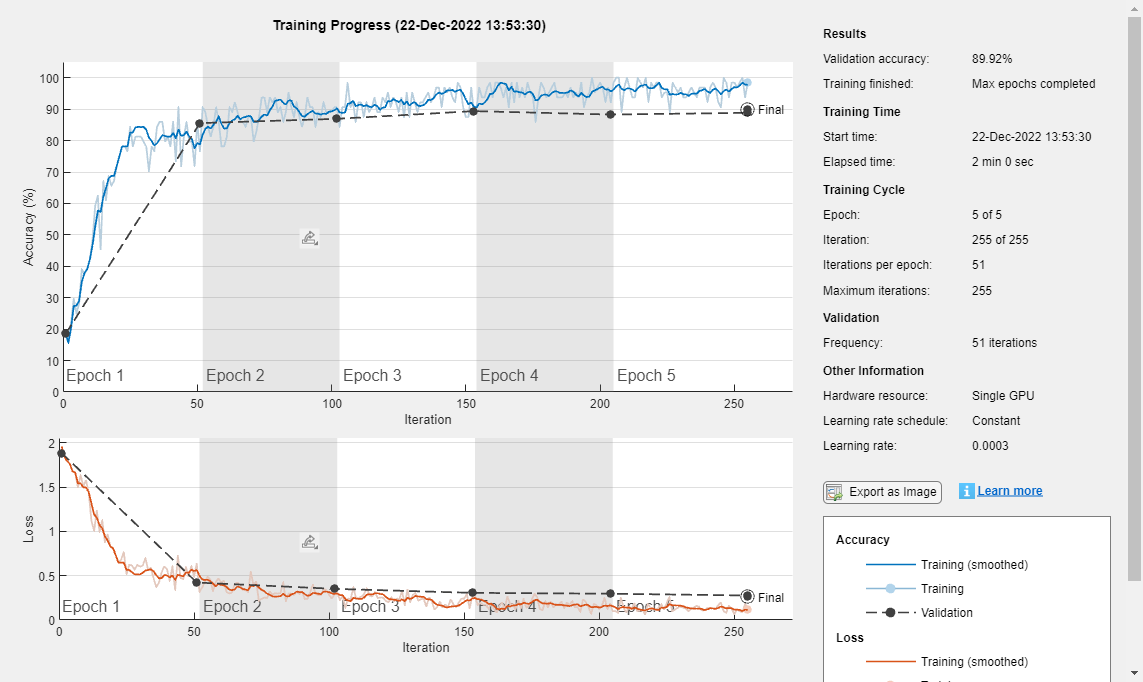

transferNet = createFlowerNetwork(net,augimdsTrain,augimdsValidation,classes);

## Evaluate Baseline Network Performance

Evaluate the performance of the `single` precision network. Performance in this case is defined as the correct classification rate.

netCCR = evaluateModelAccuracy(transferNet,augimdsValidation,validationActualLabels) 

netCCR = 0.8992

Quantize the network using the `createQuantizedNetwork` function provided at the end of this example and evaluate the performance of the quantized network. Post-training quantization of the original network yields poor performance due to the range of learnable values in the depthwise separable convolution layers. An accuracy of roughly 20% is the equivalent to guessing one of the 5 possible labels for each image.

originalQuantizedNet = createQuantizedNetwork(transferNet,augimdsCalibration);
originalQuantizedCCR = evaluateModelAccuracy(originalQuantizedNet,augimdsValidation,validationActualLabels)

originalQuantizedCCR = 0.2153

PTQaccuracyLoss = netCCR-originalQuantizedCCR

PTQaccuracyLoss = 0.6839

## Replace Network Layers with Quantization Aware Training Layers

Replace the `Convolution2D` and `GroupedConvolution2D` layers along with their adjacent `BatchNormalization` layers with custom layers that are quantization aware using the `makeQuantizationAwareLayers` function provided with this example. The quantization aware layers are custom layers that have modified `forward` and `predict` behavior that inject quantization error similar to that of post-training quantization. The quantization error comes from newly insterted operations that quantize, then unquantize a given value using best-precision scaling to `int8` precision. The quantizing and unquantizing can be referred to as "boomerang quantization". 

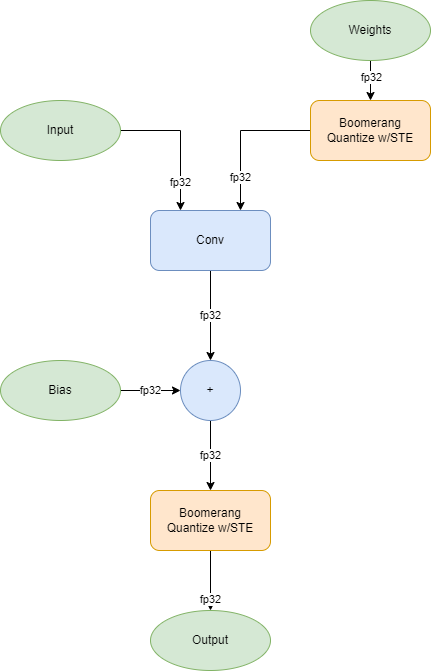

Boomerang quantization can be expressed as follows.

 
$$\begin{array}{l}
\mathrm{𝑥}̂=boomerangQuantize\left(\mathrm{𝑥}\right)\\
\;\;\;=\mathrm{unquantize}\left(\mathrm{quantize}\left(\mathrm{𝑥}\right)\right)\\
\;\;\;=\mathrm{rescale}\cdot \mathrm{saturate}\left(\mathrm{round}\left(\frac{\mathrm{𝑥}}{\mathrm{scale}}\right)\right)
\end{array}$$


The quantization contains a rounding operation that is not differentiable. During the backwards pass, calculation of gradients for a rounding operation would result in zero gradients. To avoid this problem, the layers use a straight-through estimator to estimate the gradient with an identity function [2].

 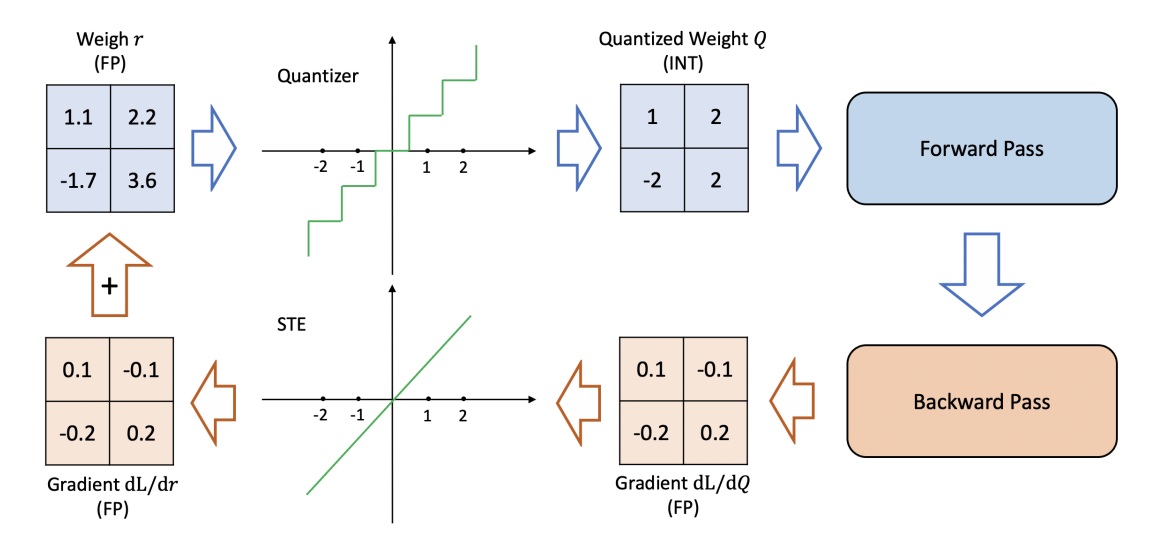

For 2-D convolution layers, the weights and biases of the replacement layers include the batch normalization layer statistics. Convolution operations furing training use the adjusted and quantized weights [3].

As the batch normalization layer statistics are incorporated into the convolution layers, the `makeQuantizationAwareLayers` replaces each batch normalization layer with an identity layer that returns its input as its output. 

quantizationAwareLayerGraph = makeQuantizationAwareLayers(transferNet);

Inspect the layers of the network.

quantizationAwareLayerGraph.Layers

ans =   154×1 Layer array with layers:

     1   'input_1'                        Image Input                         224×224×3 images with 'zscore' normalization
     2   'Conv1'                          Quantized Fused Convolution Layer   Quantization Aware Conv-BN Layer Group for Training
     3   'bn_Conv1'                       Identity Training Layer             No operation to forward behavior
     4   'Conv1_relu'                     Clipped ReLU                        Clipped ReLU with ceiling 6
     5   'expanded_conv_depthwise'        Quantized Fused Convolution Layer   Quantization Aware Conv-BN Layer Group for Training
     6   'expanded_conv_depthwise_BN'     Identity Training Layer             No operation to forward behavior
     7   'expanded_conv_depthwise_relu'   Clipped ReLU                        Clipped ReLU with ceiling 6
     8   'expanded_conv_project'          Quantized Fused Convolut

To apply quantization aware training to a network that contains convolution layers without an adjacent bach normalization layer, use the `QuantizedConvolutionTrainingLayer` provided with this example instead of `QuantizedConvolutionBatchNormTrainingLayer`.

## Do Quantization Aware Training

Using the layer graph with quantization aware training layers, train the network. Compared to the training of the original network, the training options have been modified to increase the number of `MaxEpochs` to 10 and the `ValidationFrequency` to every 2 epochs.

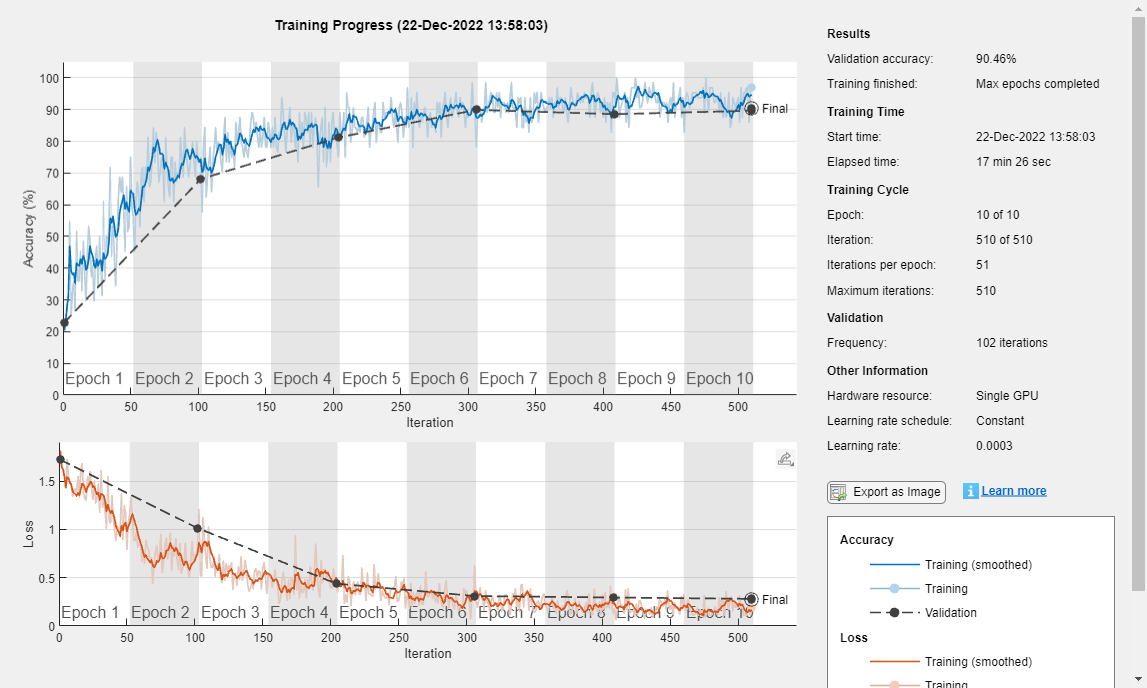

miniBatchSize = 64;
validationFrequencyEpochs = 2;
numObservations = augimdsTrain.NumObservations;
numIterationsPerEpoch = floor(numObservations/miniBatchSize);
validationFrequency = validationFrequencyEpochs*numIterationsPerEpoch;

options = trainingOptions("sgdm", ...
        MaxEpochs=10, ...
        MiniBatchSize=miniBatchSize, ...
        InitialLearnRate=3e-4, ...
        Shuffle="every-epoch", ...
        ValidationData=augimdsValidation, ...
        ValidationFrequency=validationFrequency, ...
        Plots="training-progress", ...
        Verbose=false);

quantizationAwareTrainedNet = trainNetwork(augimdsTrain,quantizationAwareLayerGraph,options);

## Quantize the Network

The network returned by the `trainNetwork` function still has quantization aware training layers. The quantization aware training operators need to be replaced with operators that are specific to inference. Whereas training was performed using pseudo-quantized 32-bit floating-point values, the quantized network must perform inference using 8-bit integer inputs and weights. 

 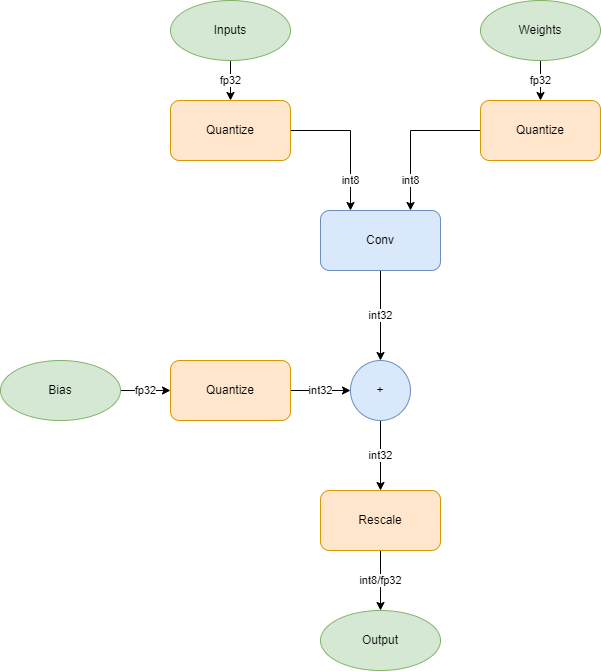

Remove the quantization aware layers and replace with underlying learned convolution layers using the `removeQuantizationAwareLayers` function, provided at the end of this example. 

preQuantizedNetwork = removeQuantizationAwareLayers(quantizationAwareTrainedNet);

Perform post-training quantization on the network as normal using the function `createQuantizedNetwork`, provided at the end of this example. 

quantizationAwareQuantizedNet = createQuantizedNetwork(preQuantizedNetwork,augimdsCalibration);
quantizedNetworkDetails = quantizationDetails(quantizationAwareQuantizedNet)

quantizedNetworkDetails = struct with fields:
            IsQuantized: 1
          TargetLibrary: "cudnn"
    QuantizedLayerNames: [105×1 string]
    QuantizedLearnables: [60×3 table]


## Evaluate the Quantized Network

Evaluate the performance of thequantized network.

quantizedNetworkCCR = evaluateModelAccuracy(quantizationAwareQuantizedNet,augimdsValidation,validationActualLabels)

quantizedNetworkCCR = 0.9074

PTQaccuracyLoss = netCCR-quantizedNetworkCCR

PTQaccuracyLoss = -0.0082

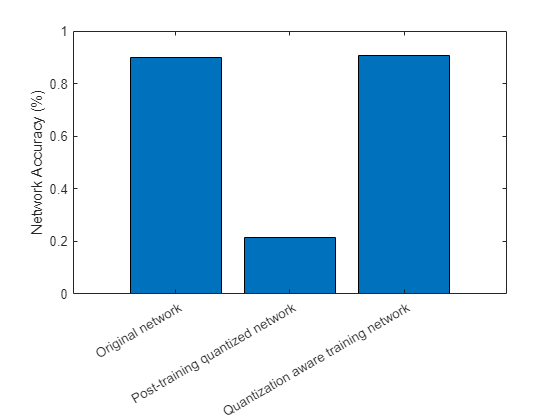

bar(categorical(["Original network","Post-training quantized network","Quantization aware training network"]),[netCCR,originalQuantizedCCR,quantizedNetworkCCR])
ylabel("Network Accuracy (%)")

The reduction in accuracy is singificantly less when using quantization aware training when compared to post-training quantization.

## References

- The TensorFlow Team. *Flowers* [http://download.tensorflow.org/example_images/flower_photos.tgz](http://download.tensorflow.org/example_images/flower_photos.tgz)

- Gholami, A., Kim, S., Dong, Z., Mahoney, M., & Keutzer, K. (2021). A Survey of Quantization Methods for Efficient Neural Network Inference. Retrieved from [https://arxiv.org/abs/2103.13630](https://arxiv.org/abs/2103.13630)

- Jacob, B., Kligys, S., Chen, B., Zhu, M., Tang, M., Howard, A., Adam, H., & Kalenichenko, D. (2017). Quantization and Training of Neural Networks for Efficient Integer-Arithmetic-Only Inference. Retrieved from [https://arxiv.org/abs/1712.05877](https://arxiv.org/abs/1712.05877)

## Supporting Functions

### Download Flower Dataset

The `downloadFlowerDataset` function downloads and extracts the flowers, if it is not yet in the current folder. 

function imageFolder = downloadFlowerDataset

    url = "http://download.tensorflow.org/example_images/flower_photos.tgz";
    downloadFolder = pwd;
    filename = fullfile(downloadFolder,"flower_dataset.tgz");
    imageFolder = fullfile(downloadFolder,"flower_photos");

    if ~exist(imageFolder,"dir")
        disp("Downloading Flower Dataset (218 MB)...")
        websave(filename,url);
        untar(filename,downloadFolder)
    end

end

### Perform Transfer Learning

The `createFlowerNetwork` function replaces the final fully connected and classification layer of the MobileNet-v2 network and retrains the nework to classify flowers.

function transfer_net = createFlowerNetwork(net,augimdsTrain,augimdsValidation,classes)

    % Define network architecture.
    % Find and replace layers to perform transfer learning.
    lgraph = layerGraph(net);

    % Replace the learnable layer with a new one.
    learnableLayer = lgraph.Layers(end-2);
    numClasses = numel(classes);
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
            Name="new_fc", ...
            WeightLearnRateFactor=10, ...
            BiasLearnRateFactor=10);
    lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

    % Replace the classification layer with a new one specific to the type
    % classes seen in the flowers dataset.
    classLayer = lgraph.Layers(end);
    newClassLayer = classificationLayer(Name="new_classoutput");
    lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

    % Specify training options.
    miniBatchSize = 64;
    validationFrequencyEpochs = 1;
    numObservations = augimdsTrain.NumObservations;
    numIterationsPerEpoch = floor(numObservations/miniBatchSize);
    validationFrequency = validationFrequencyEpochs * numIterationsPerEpoch;
    
    options = trainingOptions("sgdm", ...
        MaxEpochs=5, ...
        MiniBatchSize=miniBatchSize, ...
        InitialLearnRate=3e-4, ...
        Shuffle="every-epoch", ...
        ValidationData=augimdsValidation, ...
        ValidationFrequency=validationFrequency, ...
        Plots="training-progress", ...
        Verbose=false);

    % Train the network.
    transfer_net = trainNetwork(augimdsTrain,lgraph,options);
end

### Evaluate Mode Accuracy

The `evaluateModelAccuracy` function compares the classify output of the network with the actual labels.

function ccr = evaluateModelAccuracy(net,valDS,labels)
    ypred = classify(net,valDS);
    ccr = mean(ypred == labels);
end

### Create Quantized Network

The `createQuantizedNetwork` constructs a `dlquantizer` object for `GPU` target, simulates and collects ranges of the network with a representative datastore using the `calibrate` function, then quantizes the network using the `quantize` function.

function qNet = createQuantizedNetwork(net,calDS)
    dq = dlquantizer(net,ExecutionEnvironment="GPU");
    calResults = calibrate(dq,calDS);
    qNet = quantize(dq);
end

### Make Quantization Aware LayerGraph

The `makeQuantizationAwareLayers` function takes a `DAGNetwork` object as input and replaces 2-D convolution, grouped 2-D convolution and batch normalization layers with quantization aware versions.

function lg = makeQuantizationAwareLayers(net)
    lg = layerGraph(net);

    for idx = 1:numel(lg.Layers) - 1
        currentLayer = lg.Layers(idx);
        nextLayer = lg.Layers(idx + 1);

        % Find 2-D convolution layers or 2-D grouped convolution layers. 
        if (isa(currentLayer,"nnet.cnn.layer.Convolution2DLayer") ...
                || isa(currentLayer,"nnet.cnn.layer.GroupedConvolution2DLayer"))
                
            if isa(nextLayer,"nnet.cnn.layer.BatchNormalizationLayer")

                % Replace convolution layer with quantization aware layer.
                qLayer = QuantizedConvolutionBatchNormTrainingLayer(currentLayer,nextLayer);
                lg = replaceLayer(lg,currentLayer.Name,qLayer);

                % Replace batchNormalizationLayer with identity training
                % layer. 
                qLayer = IdentityTrainingLayer(nextLayer);
                lg = replaceLayer(lg,nextLayer.Name,qLayer);

            else
                % Replace convolution layer with quantization aware layer.
                qLayer = QuantizedConvolutionTrainingLayer(currentLayer);
                lg = replaceLayer(lg,currentLayer.Name,qLayer);
            end

        end
    end

end

### Remove Quantization Aware Layers from Network

The `removeQuantizationAwareLayers` function extract the original layers from the quantization aware network and replaces the quantization aware layers with the original underlying layers.

function net = removeQuantizationAwareLayers(qatNet)
lg = layerGraph(qatNet);

% Find quantization aware training layers and replace with the
% underlying layers.
for idx = 1:numel(lg.Layers)
    currentLayer = lg.Layers(idx);

    if isa(currentLayer,"QuantizedConvolutionBatchNormTrainingLayer")

        cLayer = currentLayer.Network.Layers(1);
        lg = replaceLayer(lg,cLayer.Name,cLayer);

        bLayer = currentLayer.Network.Layers(2);
        lg = replaceLayer(lg,bLayer.Name,bLayer);
    end
end

net = assembleNetwork(lg);

end

*Copyright 2022 The MathWorks, Inc.*